# Exercicis full 1

n=10;
sum(1:n)

n=10; p=2;
sum((1:n).^p)

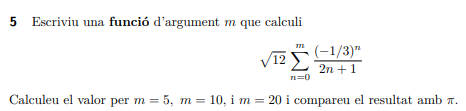

r1=sqrt(12)*sumFor(5); 
dc = abs(pi - r1)
xs= dc/pi

n=15;
x=0:n;
xn=8.^(-x);
f= @(x) sqrt(x.^2 +1)-1;
g= @(x) (x.^2) ./ sqrt(x.^2 + 1)+1;
array2table([x;xn;f(xn);g(xn)]')

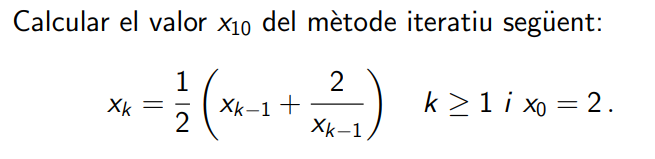

clear vars;
format shortg;
n=10;
xk=zeros(n,1);
xk(1)= 2;

for i=2:n
    xk(i)= 1/2 * (xk(i-1) + 2/xk(i-1));
end

errA = abs(sqrt(2) - xk);
errR= errA/sqrt(2);
array2table([xk,errA,errR],'VariableNames',{'xk','ErrA','ErrR'})

Mateix que l'anterior pero amb while

clear vars;
format shortg;
n=10;
k=0:n;
xk=zeros(n,1);
xk(1)= 2;
i=2;
while i < n+1
    xk(i)= 1/2 * (xk(i-1) + 2/xk(i-1));
    i=i+1;
end

errA = abs(sqrt(2) - xk);
errR= errA/sqrt(2);
array2table([xk,errA,errR],'VariableNames',{'xk','ErrA','ErrR'})

El mateix pero amb condicio d'aturada

clear vars;
format shortg;
tolMax=0.5e-10;
n=11;
x=0:n-1;
xk=zeros(n,1);
errA=ones(n,1);
errR=ones(n,1);
xk(1)= 2;
i=2;
while i <= n && errA(i) > tolMax
    
    xk(i)= 1/2 * (xk(i-1) + 2/xk(i-1));
    errA(i)= abs(sqrt(2) - xk(i));
    errR(i)= errA(i)/sqrt(2);
    i=i+1;
end
array2table([x',xk,errA,errR],'VariableNames',{'x','xk','ErrA','ErrR'})

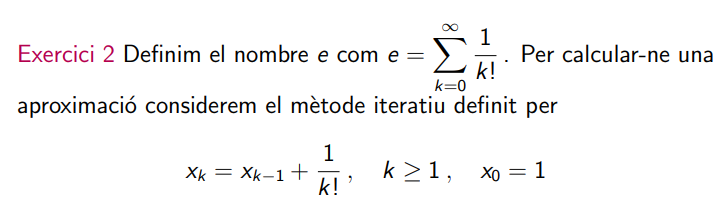

clear vars;
format shortg;
tolMax=0.5e-10;


function [res] = sumFor(m)
res=0;
p=(-1/3);
for n=0:m
   p=1;
   res= res + p/(2*n+1);
end
end